# NearFieldToFarField manual

The NearFieldToFarField software compute the Far-Field pattern from the Near-Field data.

## software structure

the software has the compacted `Main` class for simpliest application for Near-Field measurements. It will provide the spectrum analysis and the directivity pattern .

For more complex setup and simulation, please use the `NearFieldToFarField` class and `AutField` for utilising all functionalities.

The software first parse the Near-Field data as well as the scanning grid, form them into structures and compute the corresponding data.

clc; clear variables; close all; format long;

disp("Sample usage of the application");

Sample usage of the application


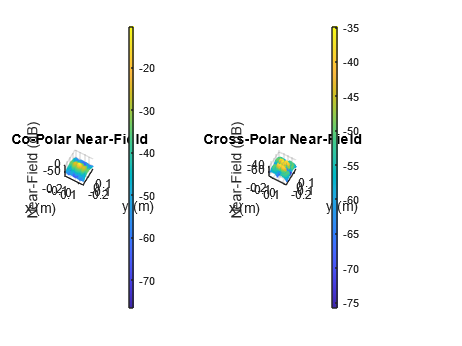

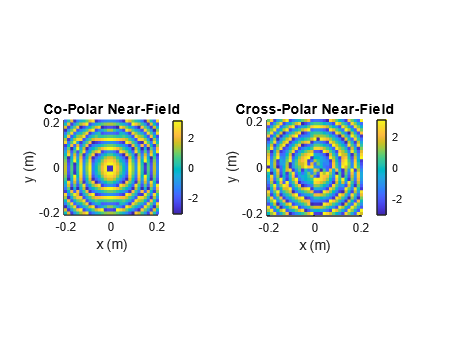

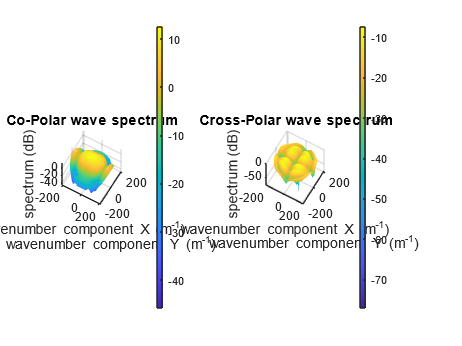

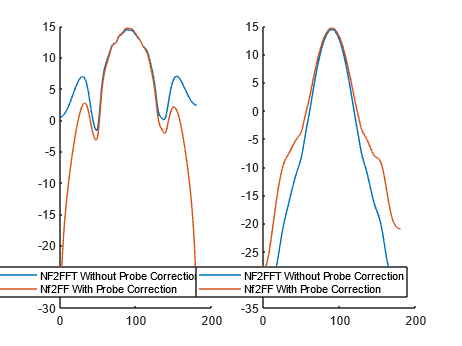


load("../Result/Example/sParamX_32.mat", "nfGrid", "sParamX");
load("../Result/Example/sParamY_32.mat", "sParamY");

FREQUENCY = 10e9;

main = Main();

main.xGrid = nfGrid.x;
main.yGrid = nfGrid.y;
main.phasorX = sParamX;
main.phasorY = sParamY;
main.frequency = FREQUENCY;

main = main.Transform();

**You can skip the rest if you do not need go deeper into details**

### `PlanarGrid` and `AngularGrid`

These data structures are for Near-Field and Far-Field meshgrid sampling points.

`PlanarGrid` create x- and y- meshgrids for rectangular coordinates, while `AngularGrid` create phi- and theta- meshgrid for angular coordinates.

disp("Example of PlanarGrid and AngularGrid");

Example of PlanarGrid and AngularGrid



SAMPLING_POINT_X = 3;
SAMPLING_POINT_Y = 3;
LENGTH_X = 3;
LENGTH_Y = 3;
disp("The warning shows that the sampling points should a power" + ...
    "of 2 to apply the FFT effectively, just ignore it as for now");

The warning shows that the sampling points should a powerof 2 to apply the FFT effectively, just ignore it as for now


xyGrid = PlanarGrid(SAMPLING_POINT_X, ...
                    SAMPLING_POINT_Y, ...
                    LENGTH_X,         ...
                    LENGTH_Y);

disp("PlanarGrid provides x- and y- meshgrid");

PlanarGrid provides x- and y- meshgrid


disp(xyGrid);

  PlanarGrid with properties:

    x: [3x3 double]
    y: [3x3 double]




disp("AngularGrid provides phi- and theta- meshgrid");

AngularGrid provides phi- and theta- meshgrid


phithetaGrid = AngularGrid(0.005);
disp(phithetaGrid);

  AngularGrid with properties:

    theta: [628x628 double]
      phi: [628x628 double]



Now, you think, what the usage of meshgrid is. This is quite useful when handling grid-based quantities. For example, Near-Field data is a grid-based quantity. In this application, every mesh-grid quantity always contains 2 components, either x- and y- components, or phi- and theta- components.

clear variables;
load("../Result/Example/sParamX_32.mat", "nfGrid", "sParamX");
load("../Result/Example/sParamY_32.mat", "sParamY");

disp("Sample usage of PlanarGrid");

Sample usage of PlanarGrid



disp("The x- and y- grid of the Near-Field data");

The x- and y- grid of the Near-Field data


disp(nfGrid);

  PlanarGrid with properties:

    x: [32x32 double]
    y: [32x32 double]




fprintf("x-grid has the size of %d x %d", size(nfGrid.x));

x-grid has the size of 32 x 32

fprintf("y-grid has the size of %d x %d", size(nfGrid.y));

y-grid has the size of 32 x 32


disp("Near-Field contains of 2 components");

Near-Field contains of 2 components


fprintf("co-polar component sParamX with size %d x %d", size(sParamX));

co-polar component sParamX with size 32 x 32

fprintf("cross-polar component sParamY also with size %d x %d", size(sParamY));

cross-polar component sParamY also with size 32 x 32

### `MeshgridQuantity`

`To effectively display a mesh-grid quantity, I create a data structure for this.`

nearField_MeshgridQuantity = MeshgridQuantity(nfGrid.x, nfGrid.y, sParamX, sParamY, "20log");
disp("display Near-Field data");

display Near-Field data


figure();
ax(1) = subplot(1,2,1);
ax(2) = subplot(1,2,2);
surface(nearField_MeshgridQuantity, ax(1), ax(2));

disp("display Near-Field data in another point-of-view");

display Near-Field data in another point-of-view


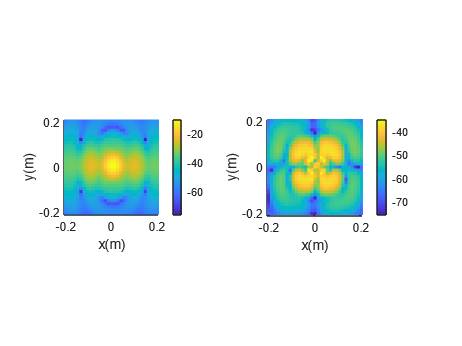

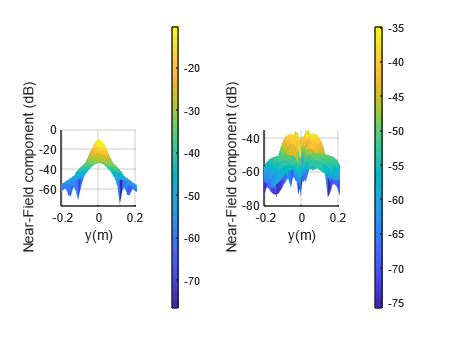

figure();
ax(3) = subplot(1,2,1);
ax(4) = subplot(1,2,2);
surface(nearField_MeshgridQuantity, ax(3), ax(4), [90, 0]);
xlabel(ax, "x(m)");
ylabel(ax, "y(m)");
zlabel(ax, "Near-Field component (dB)");

### `VectorQuantity`

vector here is a 1D matrix, which is used for the quantities like the 2D cut of the pattern.

clear variables;

disp("Example usage of VectorQuantity");

Example usage of VectorQuantity



load("../Result/Example/pattern.mat");

disp("display XZ-plane and YZ-plane component of the pattern");

display XZ-plane and YZ-plane component of the pattern


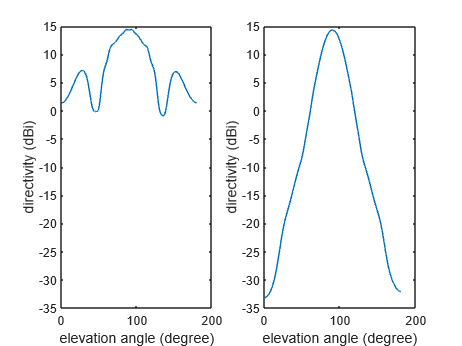

figure();
ax(1) = subplot(1,2,1);
singlePlot(patternX, ax(1));
ax(2) = subplot(1,2,2);
singlePlot(patternY, ax(2));
ylim(ax, [-35, 15]);
xlabel(ax, "elevation angle (degree)");
ylabel(ax, "directivity (dBi)");

### `AutField`

This class is used to acquire Near-Field data.

For documentation of antenna modelling, please review [MATLAB Antenna Toolbox Catalog](https://ch.mathworks.com/help/antenna/antenna-catalog.html).

For example, I design a horn antenna with all parameters and the scanning plane defined and use this class to acquire the Near-Field data.

clear variables;

disp("Example of designing antenna model and acquiring Near-Field");

Example of designing antenna model and acquiring Near-Field



%% define constants
FREQUENCY = 10e9;
SPEED_OF_LIGHT = 299792458;
WAVELENGTH = SPEED_OF_LIGHT / FREQUENCY;

%% parameters of the open-ended rectangular waveguide
% standard: WR-90
GUIDE_HEIGHT = 10.16e-3;
GUIDE_WIDTH  = 22.86e-3;

%% parameters of the horn antenna
% type:  PM7320x
FLARE_LENGTH = 130e-3;
FLARE_WIDTH  = 75e-3;
FLARE_HEIGHT = 50e-3;

%% design horn antenna
hornAnt             = design(horn, FREQUENCY);
hornAnt.Height      = GUIDE_HEIGHT;
hornAnt.Width       = GUIDE_WIDTH;
hornAnt.FlareLength = FLARE_LENGTH;
hornAnt.FlareWidth  = FLARE_WIDTH;
hornAnt.FlareHeight = FLARE_HEIGHT;
hornAnt.Tilt        = [-90, 180];
hornAnt.TiltAxis    = [0 1 0; 0 0 1];

% the scanning distance is from the aperture of the antenna
SCANNING_DISTANCE   = hornAnt.Length/2 + FLARE_LENGTH + 13e-2;

%% define near-field and far-field scanning grids
SAMPLING_POINT_X = 32;
SAMPLING_POINT_Y = SAMPLING_POINT_X;
GRID_SPACE       = 0.015; 
LENGTH_X         = SAMPLING_POINT_X * GRID_SPACE;
LENGTH_Y         = LENGTH_X;

nfGrid = PlanarGrid(SAMPLING_POINT_X, SAMPLING_POINT_Y, LENGTH_X, LENGTH_Y);
ffGrid = AngularGrid(0.002);

%% generate near-field data
hornAntField = AutField(hornAnt, FREQUENCY, nfGrid, ffGrid, SCANNING_DISTANCE);
disp("display Near-Field data acquired from the model");

display Near-Field data acquired from the model


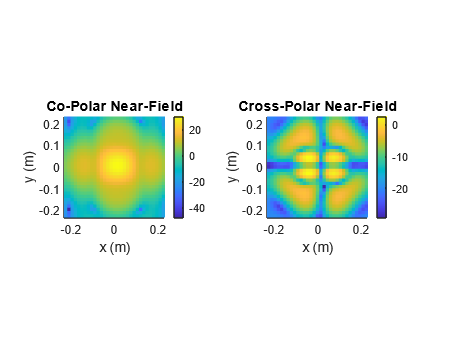

displayNearField(hornAntField);

disp("display radiation pattern of the antenna model");

display radiation pattern of the antenna model


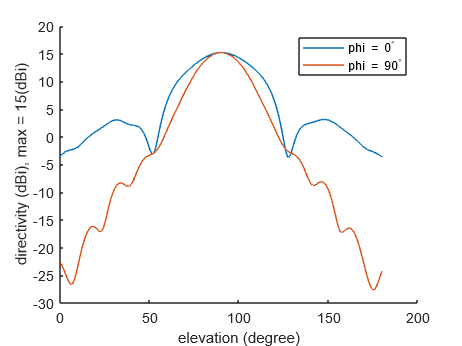

displayDirectivity(hornAntField);

After acquiring the Near-Field data, either from the simulation or from measurements, we can feed the data to the `NearFieldToFarField` class for further evaluation.

For instance, let's assume that we have the measured data. The `Main` class is a wrapper for NearFieldToFarField class to abstract the setting up stuff.

clear variables;

disp("Example of preparing Near-Field data for NearFieldToFarField");

Example of preparing Near-Field data for NearFieldToFarField


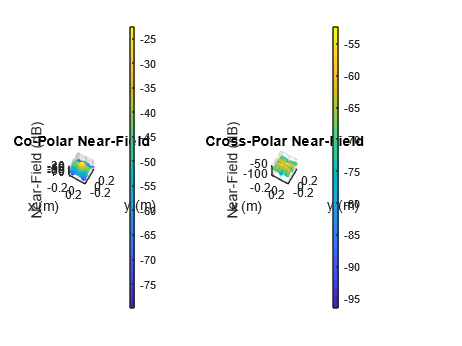

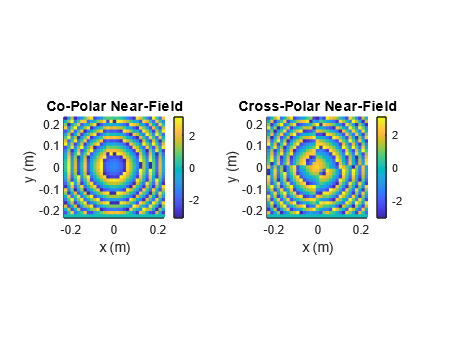

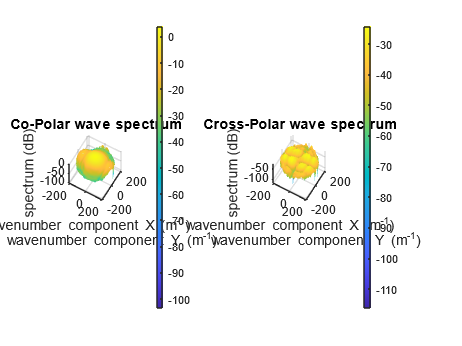

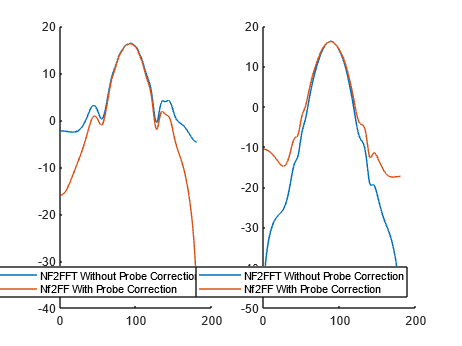


load("../Result/Example/coPolar_32.mat", "mag", "phase", "xCor", "yCor");

xGrid = xCor'/ 100; % convert to m
yGrid = yCor'/ 100;

magX_dB = mag;
magX = 10.^(magX_dB / 20); % convert to linear scale
phaseX = deg2rad(phase); % convert to radian
phasorX = magX .* exp(1j * phaseX);

load("../Result/Example/crossPolar_32.mat", "mag", "phase");

magY_dB = mag;
magY = 10.^(magY_dB / 20);
phaseY = deg2rad(phase); % convert to radian
phasorY = magY .* exp(1j * phaseY);

FREQUENCY = 10e9;

main = Main();

main.xGrid = xGrid;
main.yGrid = yGrid;
main.phasorX = phasorX;
main.phasorY = phasorY;
main.frequency = FREQUENCY;

main = main.Transform();

## Further demo

To directly utilise the `NearFieldToFarField, please refer to the examples in the repo.`